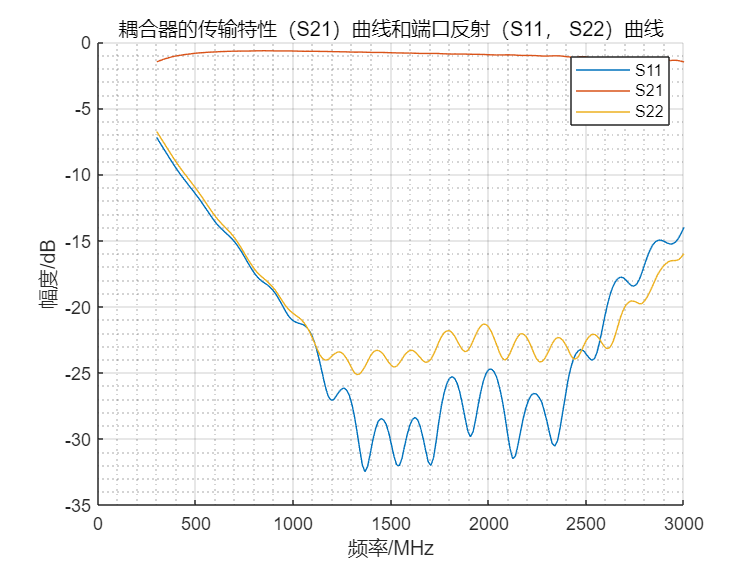

clear;clc;

S21dc2=load('S21dc2.s2p');
f=S21dc2(:,1);
S11=S21dc2(:,2)+1i*S21dc2(:,3);
S21=S21dc2(:,4)+1i*S21dc2(:,5);
S12=S21dc2(:,6)+1i*S21dc2(:,7);
S22=S21dc2(:,8)+1i*S21dc2(:,9);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
plot(f/1e6,20*log10(abs(S11)));
plot(f/1e6,20*log10(abs(S21)));
plot(f/1e6,20*log10(abs(S22)));
title('耦合器的传输特性（S21）曲线和端口反射（S11， S22）曲线');
legend('S11','S21','S22');
xlabel('频率/MHz');
ylabel('幅度/dB');

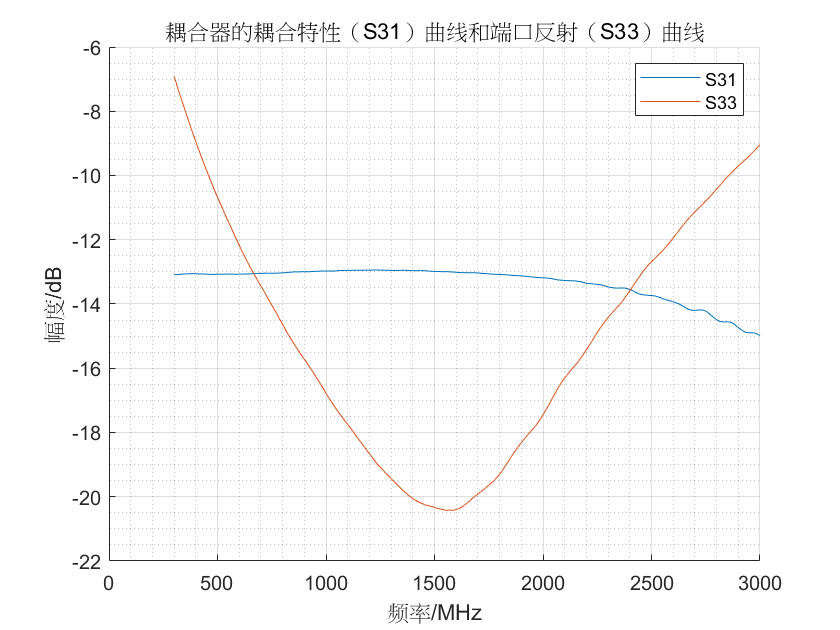

S31dc2=load('S31dc2.s2p');
f_31=S31dc2(:,1);
S11_31=S31dc2(:,2)+1i*S31dc2(:,3);
S21_31=S31dc2(:,4)+1i*S31dc2(:,5);
S12_31=S31dc2(:,6)+1i*S31dc2(:,7);
S22_31=S31dc2(:,8)+1i*S31dc2(:,9);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
plot(f/1e6,20*log10(abs(S21_31)));
plot(f/1e6,20*log10(abs(S22_31)));
title('耦合器的耦合特性（S31）曲线和端口反射（S33）曲线');
legend('S31','S33');
xlabel('频率/MHz');
ylabel('幅度/dB');

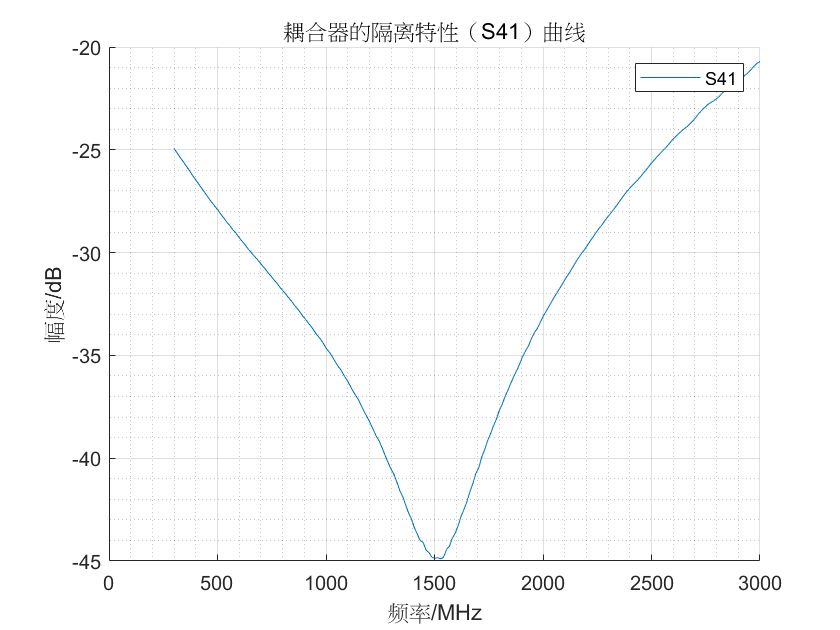

S41dc2=load('S41dc2.s2p');
f_41=S41dc2(:,1);
S21_41=S41dc2(:,4)+1i*S41dc2(:,5);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
plot(f/1e6,20*log10(abs(S21_41)));
title('耦合器的隔离特性（S41）曲线');
legend('S41');
xlabel('频率/MHz');
ylabel('幅度/dB');

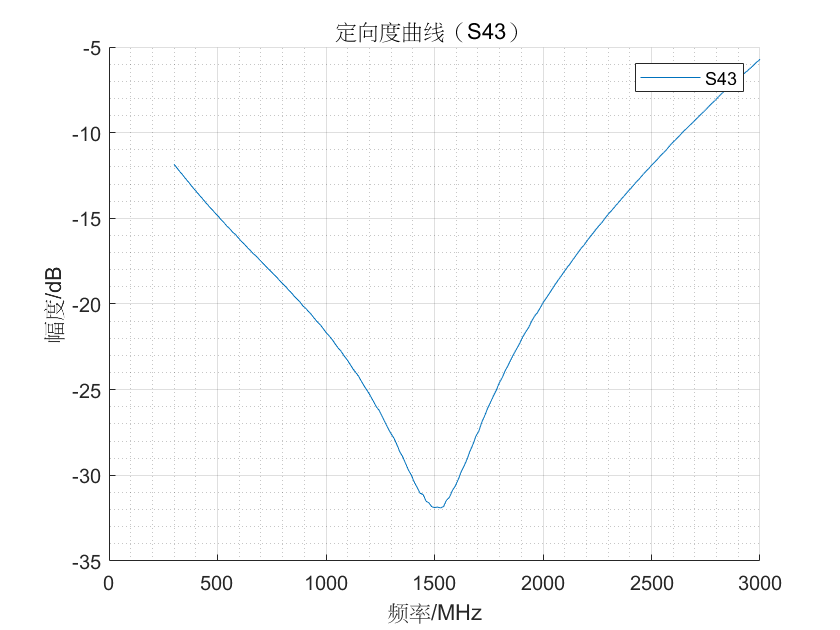

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
S43=S21_41./S21_31;
plot(f/1e6,20*log10(abs(S43)));
title('定向度曲线（S43） ');
legend('S43');
xlabel('频率/MHz');
ylabel('幅度/dB');

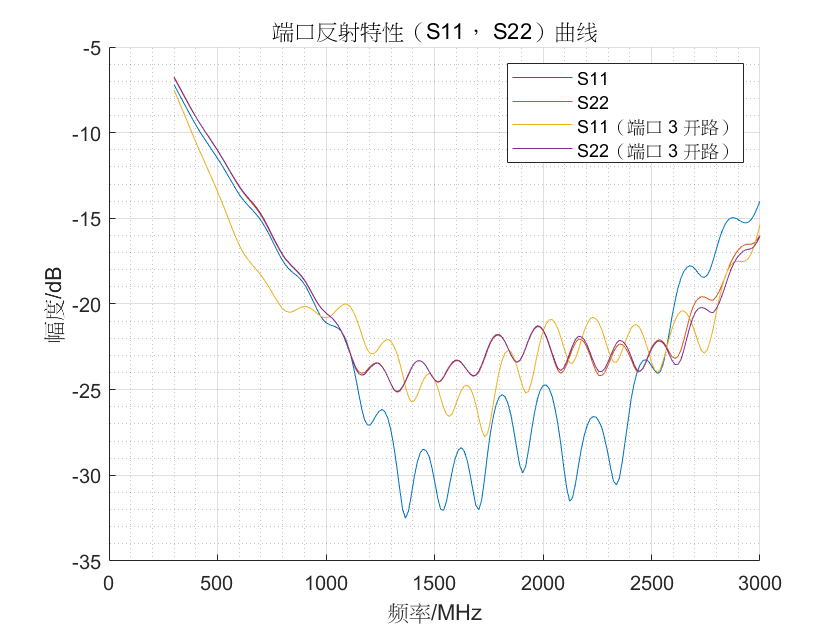

S21_2dc2=load('S21_2dc2.s2p');
f=S21_2dc2(:,1);
S11_2=S21_2dc2(:,2)+1i*S21_2dc2(:,3);
S21_2=S21_2dc2(:,4)+1i*S21_2dc2(:,5);
S22_2=S21_2dc2(:,8)+1i*S21_2dc2(:,9);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
plot(f/1e6,20*log10(abs(S11)));
plot(f/1e6,20*log10(abs(S22)));
plot(f/1e6,20*log10(abs(S11_2)));
plot(f/1e6,20*log10(abs(S22_2)));
title('端口反射特性（S11， S22）曲线');
legend('S11','S22','S11（端口 3 开路） ','S22（端口 3 开路） ');
xlabel('频率/MHz');
ylabel('幅度/dB');

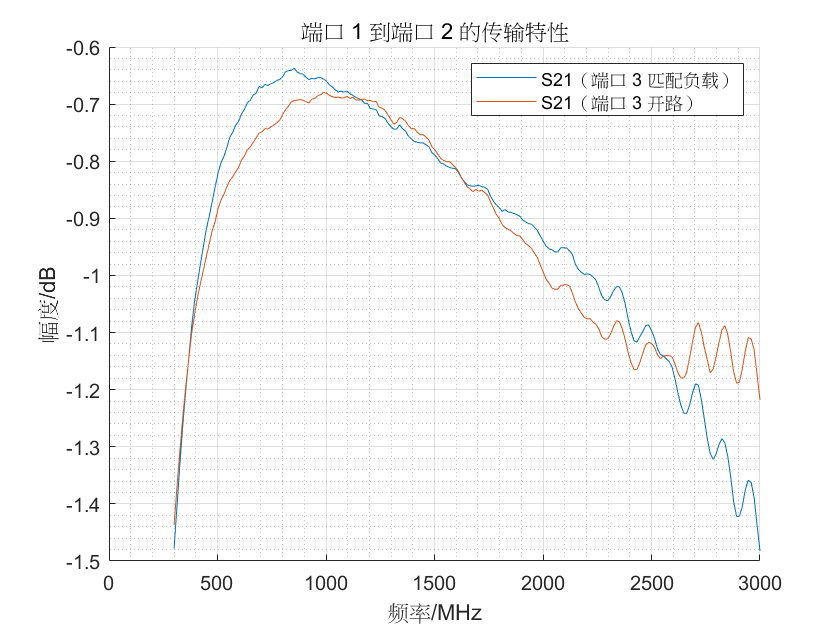

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘图%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();
grid on;grid minor;
hold on;
plot(f/1e6,20*log10(abs(S21)));
plot(f/1e6,20*log10(abs(S21_2)));
title('端口 1 到端口 2 的传输特性');
legend('S21（端口 3 匹配负载） ','S21（端口 3 开路） ');
xlabel('频率/MHz');
ylabel('幅度/dB');